# ELEN 133 Homework 7 -- Ayden Dauenhauer

## Question 3

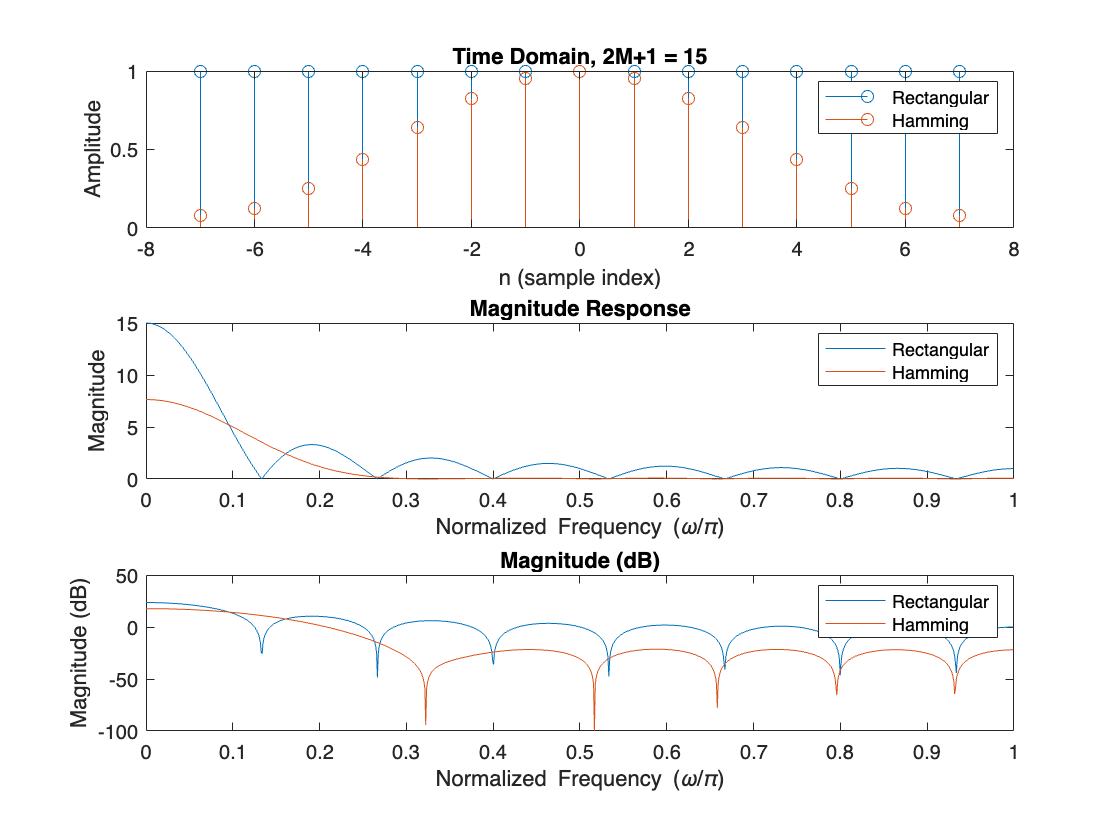

% 2M+1=15
M = 7;
width = 2*M + 1;
n = -M:M;

rectangular = ones(1, width);
hamming = 0.54 + 0.46*cos(pi*n/M);

N = 1024;
[H_rectangular, w] = freqz(rectangular, 1, N);
H_hamming = freqz(hamming, 1, N);

figure;
subplot(3,1,1);
stem(n, rectangular);
hold on;
stem(n, hamming);
title('Time Domain, 2M+1 = 15');
xlabel('n (sample index)');
ylabel('Amplitude');
legend('Rectangular', 'Hamming');

subplot(3,1,2);
plot(w/pi, abs(H_rectangular));
hold on;
plot(w/pi, abs(H_hamming));
title('Magnitude Response');
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Magnitude');
legend('Rectangular', 'Hamming');

subplot(3,1,3);
plot(w/pi, 20*log10(abs(H_rectangular)));
hold on;
plot(w/pi, 20*log10(abs(H_hamming)));
title('Magnitude (dB)');
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Magnitude (dB)');
legend('Rectangular', 'Hamming');

**Find the width of the main lobe and the maximum gain of the side lobes.**

    width, rectangular = 0.14

    gain, rectangular = -50 dB

    width, rectangular = 0.333

    gain, hamming = -90 dB

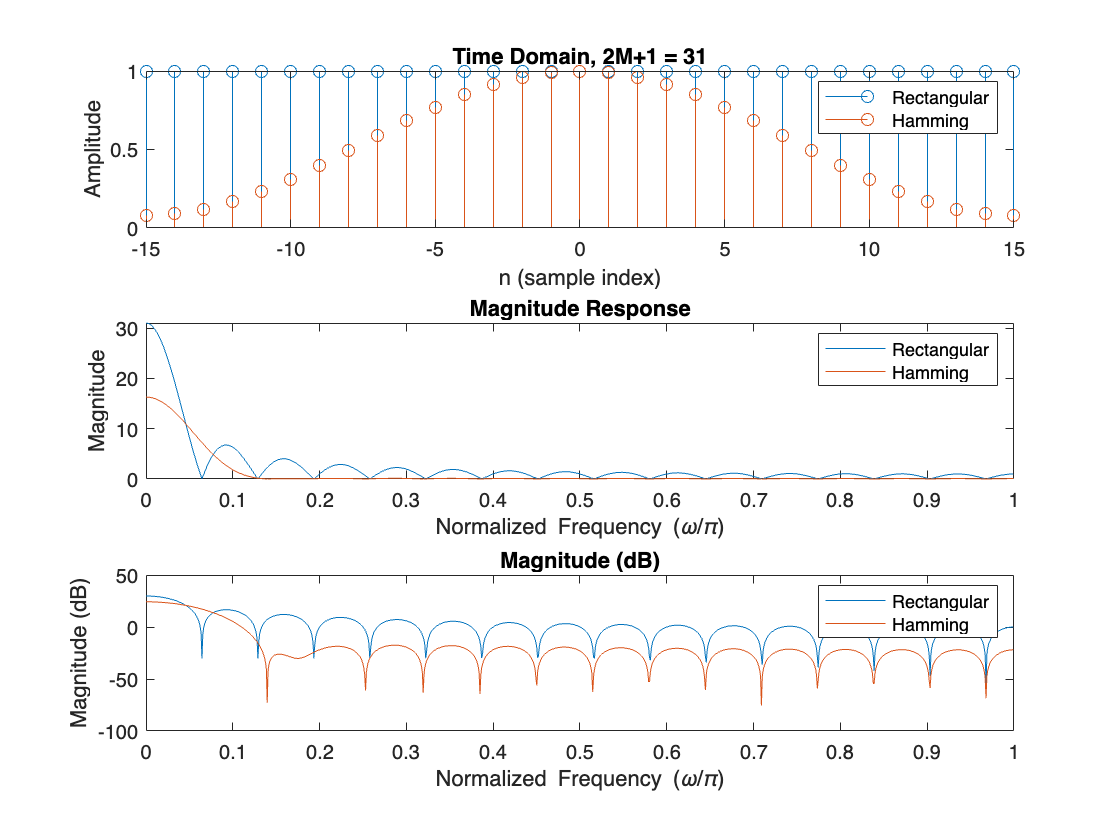

% 2M+1=31
M = 15;
width = 2*M + 1;
n = -M:M;

rectangular = ones(1, width);
hamming = 0.54 + 0.46*cos(pi*n/M);

N = 1024;
[H_rectangular, w] = freqz(rectangular, 1, N);
H_hamming = freqz(hamming, 1, N);

figure;
subplot(3,1,1);
stem(n, rectangular);
hold on;
stem(n, hamming);
title('Time Domain, 2M+1 = 31');
xlabel('n (sample index)');
ylabel('Amplitude');
legend('Rectangular', 'Hamming');

subplot(3,1,2);
plot(w/pi, abs(H_rectangular));
hold on;
plot(w/pi, abs(H_hamming));
title('Magnitude Response');
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Magnitude');
legend('Rectangular', 'Hamming');

subplot(3,1,3);
plot(w/pi, 20*log10(abs(H_rectangular)));
hold on;
plot(w/pi, 20*log10(abs(H_hamming)));
title('Magnitude (dB)');
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Magnitude (dB)');
legend('Rectangular', 'Hamming');

**Find the width of the main lobe and the maximum gain of the side lobes.**

    width, rectangular = 0.07

    gain, rectangular = -45 dB

    width, rectangular = 0.14

    gain, hamming = -70 dB

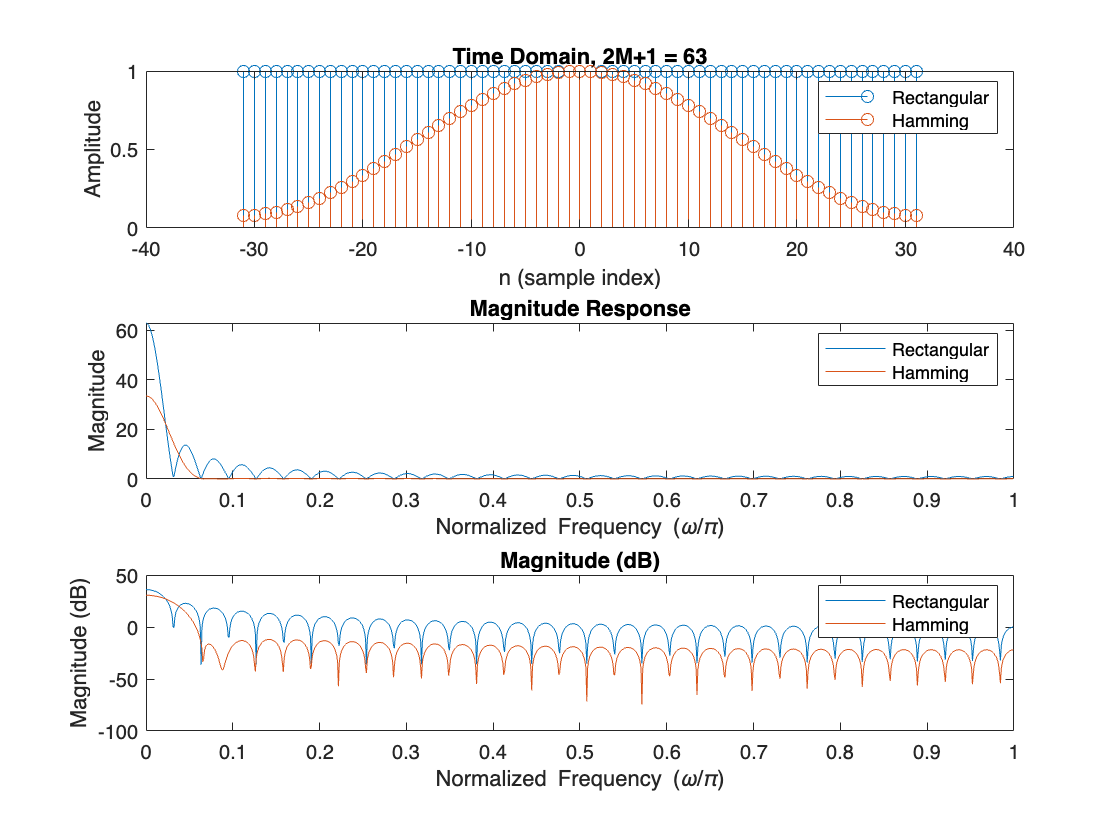

% 2M+1=63
M = 31;
width = 2*M + 1;
n = -M:M;

rectangular = ones(1, width);
hamming = 0.54 + 0.46*cos(pi*n/M);

N = 1024;
[H_rectangular, w] = freqz(rectangular, 1, N);
H_hamming = freqz(hamming, 1, N);

figure;
subplot(3,1,1);
stem(n, rectangular);
hold on;
stem(n, hamming);
title('Time Domain, 2M+1 = 63');
xlabel('n (sample index)');
ylabel('Amplitude');
legend('Rectangular', 'Hamming');

subplot(3,1,2);
plot(w/pi, abs(H_rectangular));
hold on;
plot(w/pi, abs(H_hamming));
title('Magnitude Response');
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Magnitude');
legend('Rectangular', 'Hamming');

subplot(3,1,3);
plot(w/pi, 20*log10(abs(H_rectangular)));
hold on;
plot(w/pi, 20*log10(abs(H_hamming)));
title('Magnitude (dB)');
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Magnitude (dB)');
legend('Rectangular', 'Hamming');

**Find the width of the main lobe and the maximum gain of the side lobes.**

    width, rectangular = 0.04

    gain, rectangular = -35 dB

    width, rectangular = 0.7

    gain, hamming = -70 dB

## Question 4

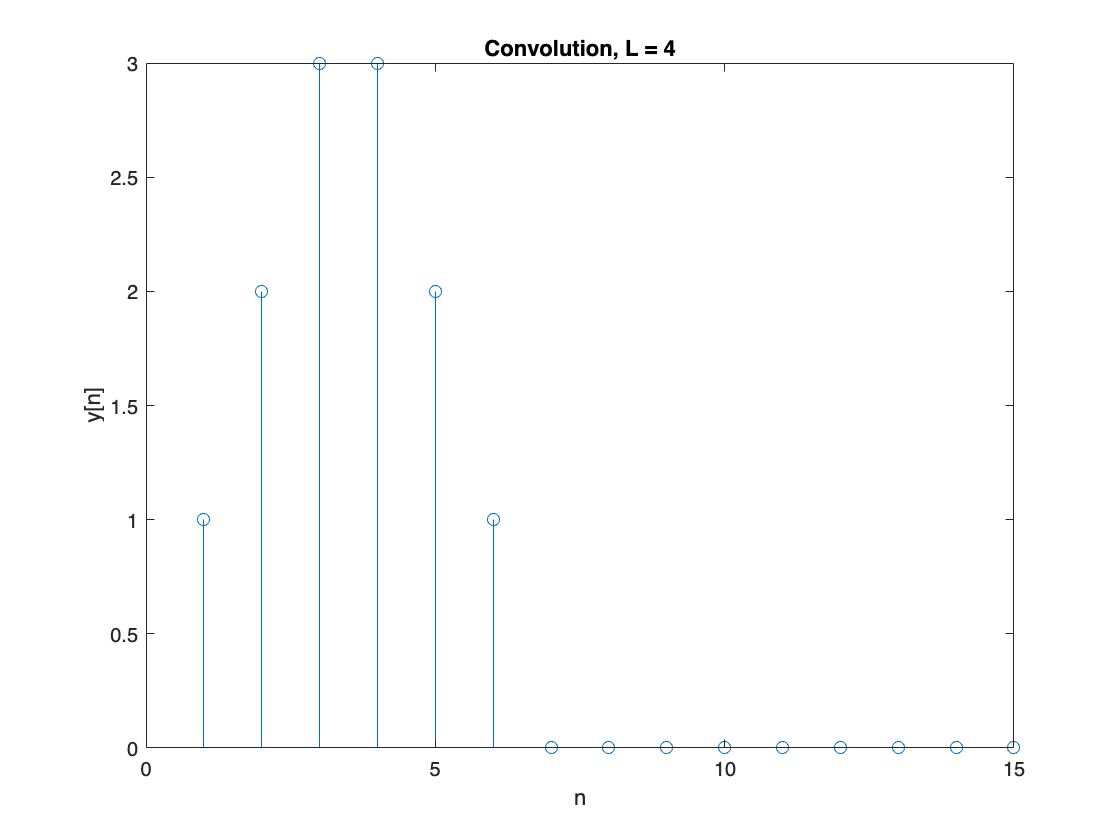

% Part a + b
% L = 4;
x1 = [1 1 1 1 0 0 0 0];
x2 = [1 1 1 0 0 0 0 0];
y = conv(x1, x2);
figure;
stem(y);
title('Convolution, L = 4');
xlabel('n');
ylabel('y[n]');

**What is the length of y which has nonzero sample values?**

    Length of y which has nonzero sample values = 6

X1 = fft(x1, 8);
X2 = fft(x2, 8);
Y2 = X1 .* X2;
y2 = ifft(Y2)

y2 =     1.0000    2.0000    3.0000    3.0000    2.0000    1.0000         0         0


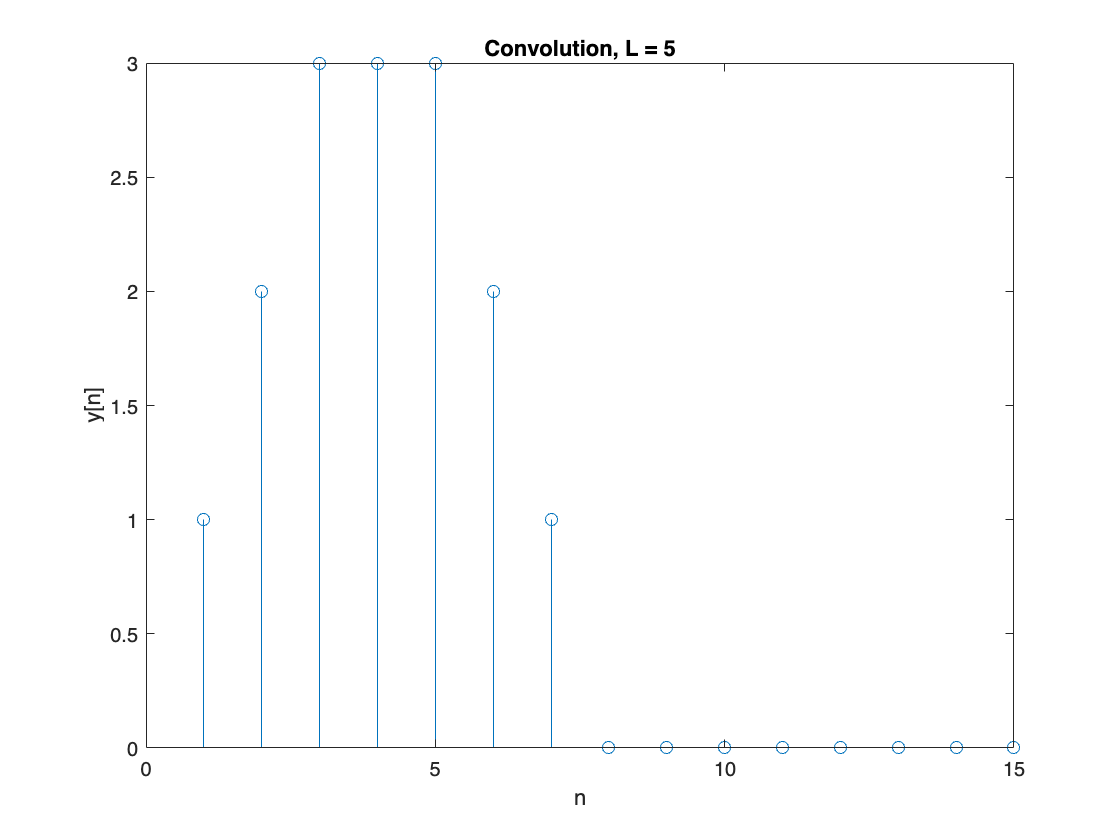

% L = 5;
x1 = [1 1 1 1 1 0 0 0];
x2 = [1 1 1 0 0 0 0 0];
y = conv(x1, x2);
figure;
stem(y);
title('Convolution, L = 5');
xlabel('n');
ylabel('y[n]');

**What is the length of y which has nonzero sample values?**

    Length of y which has nonzero sample values = 7

X1 = fft(x1, 8);
X2 = fft(x2, 8);
Y2 = X1 .* X2;
y2 = ifft(Y2)

y2 =      1     2     3     3     3     2     1     0


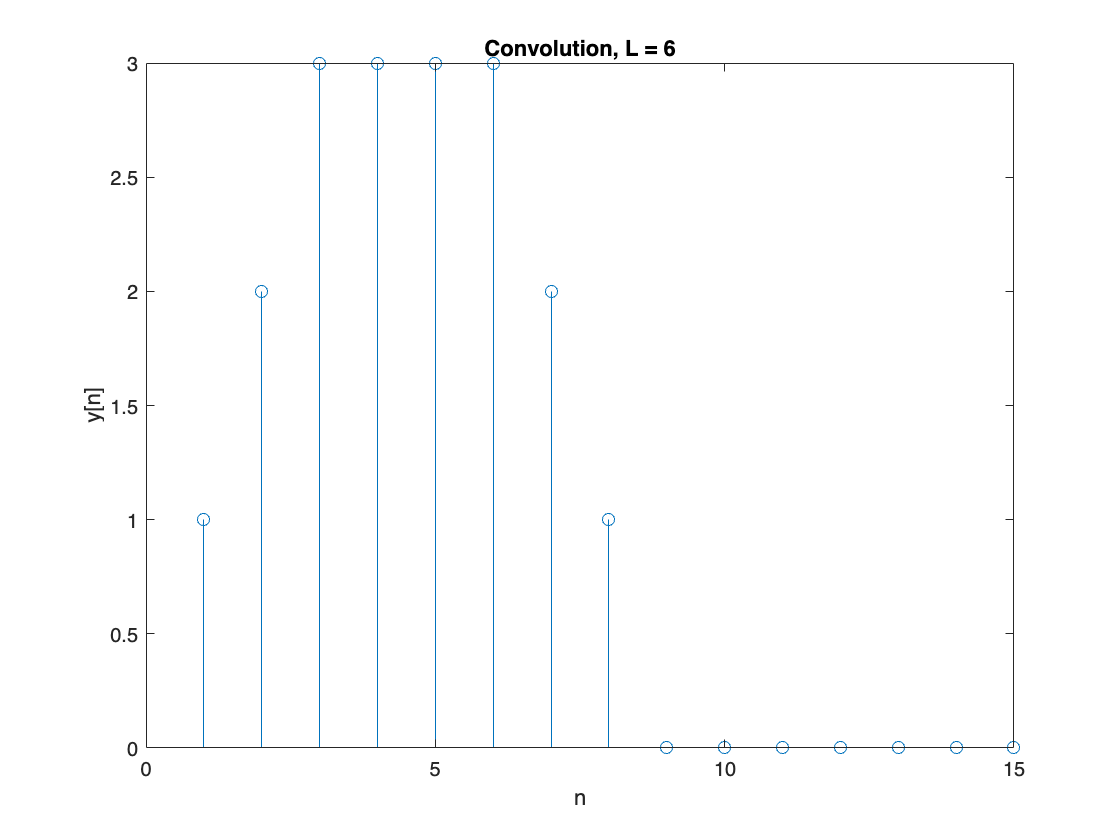

% L = 6;
x1 = [1 1 1 1 1 1 0 0];
x2 = [1 1 1 0 0 0 0 0];
y = conv(x1, x2);
figure;
stem(y);
title('Convolution, L = 6');
xlabel('n');
ylabel('y[n]');

**What is the length of y which has nonzero sample values?**

    Length of y which has nonzero sample values = 8

X1 = fft(x1, 8);
X2 = fft(x2, 8);
Y2 = X1 .* X2;
y2 = ifft(Y2)

y2 =      1     2     3     3     3     3     2     1


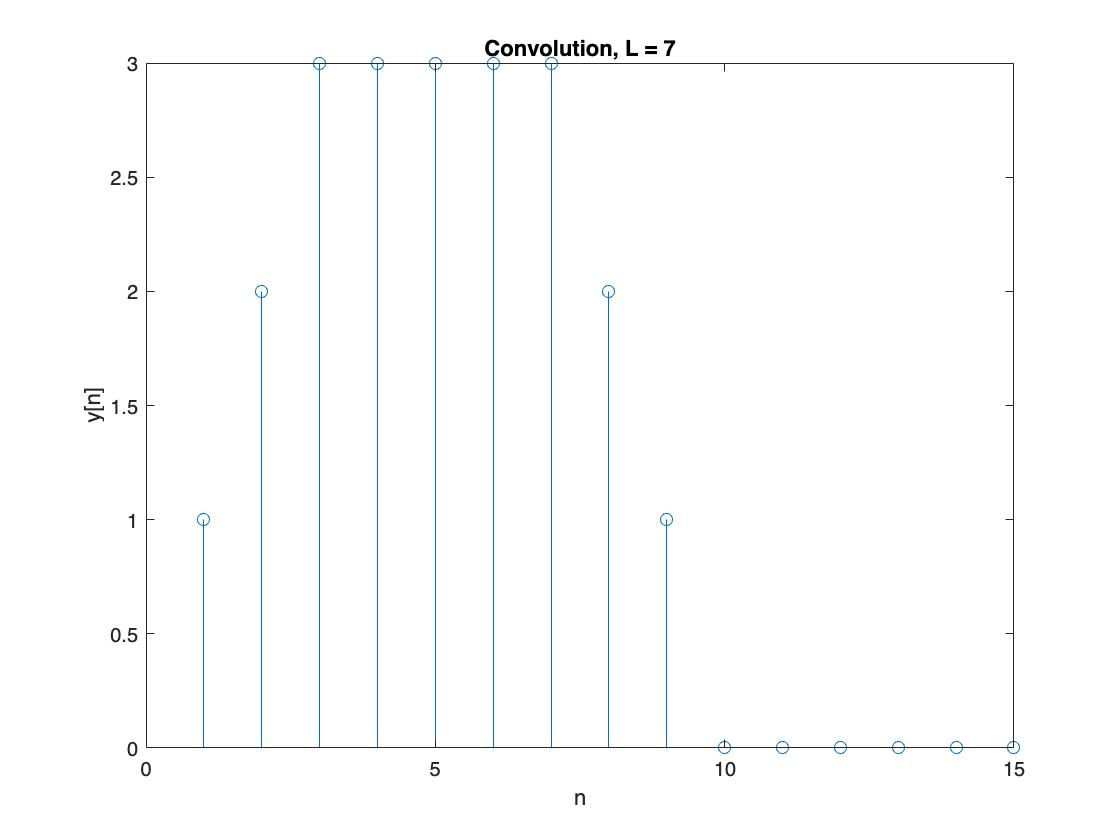

% L = 7;
x1 = [1 1 1 1 1 1 1 0];
x2 = [1 1 1 0 0 0 0 0];
y = conv(x1, x2);
figure;
stem(y);
title('Convolution, L = 7');
xlabel('n');
ylabel('y[n]');

**What is the length of y which has nonzero sample values?**

    Length of y which has nonzero sample values = 9

X1 = fft(x1, 8);
X2 = fft(x2, 8);
Y2 = X1 .* X2;
y2 = ifft(Y2)

y2 =      2     2     3     3     3     3     3     2


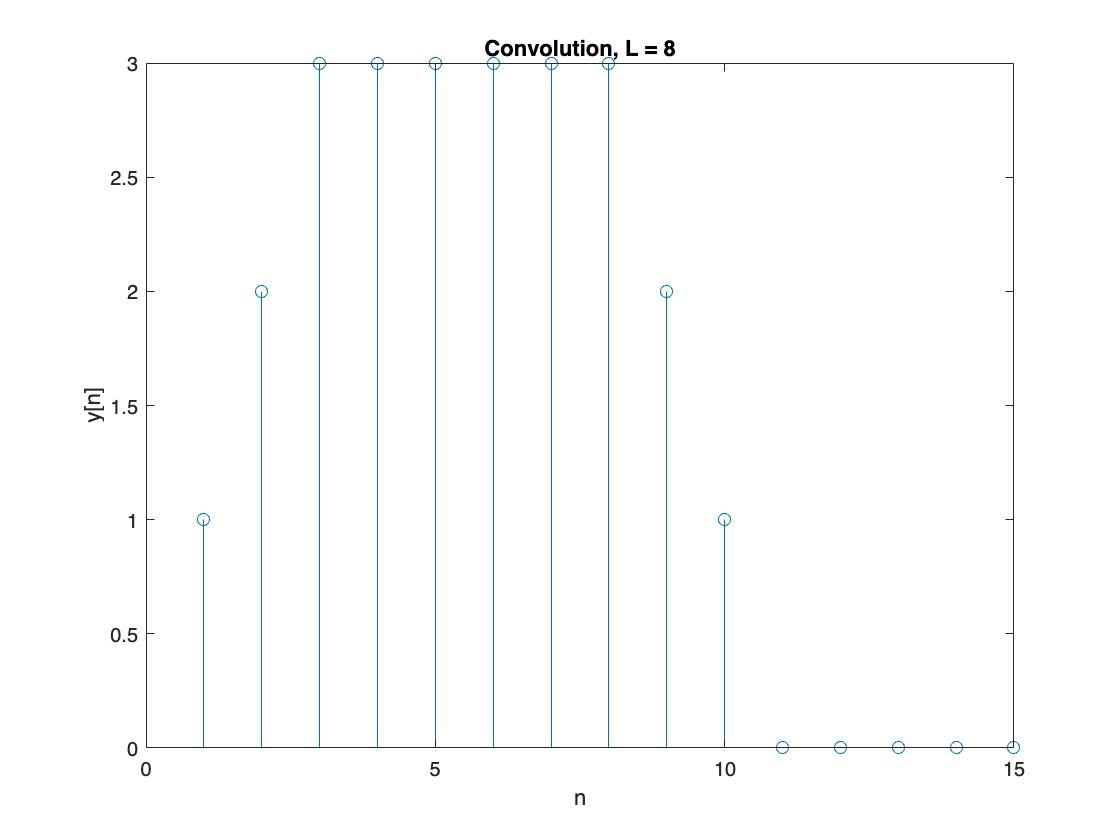

% L = 8;
x1 = [1 1 1 1 1 1 1 1];
x2 = [1 1 1 0 0 0 0 0];
y = conv(x1, x2);
figure;
stem(y);
title('Convolution, L = 8');
xlabel('n');
ylabel('y[n]');

**What is the length of y which has nonzero sample values?**

    Length of y which has nonzero sample values = 10

**In general, how many samples are in y when two inputs of length 8 are convolved?**

    There are 15 samples in y when two inputs of length 8 are convolved. 

X1 = fft(x1, 8);
X2 = fft(x2, 8);
Y2 = X1 .* X2;
y2 = ifft(Y2)

y2 =      3     3     3     3     3     3     3     3


### **Part c:**

**Compare y2 from part (b) to your convolution results from part (a). For what values of L are they the same? When they are not the same, why are they different?**

    temp

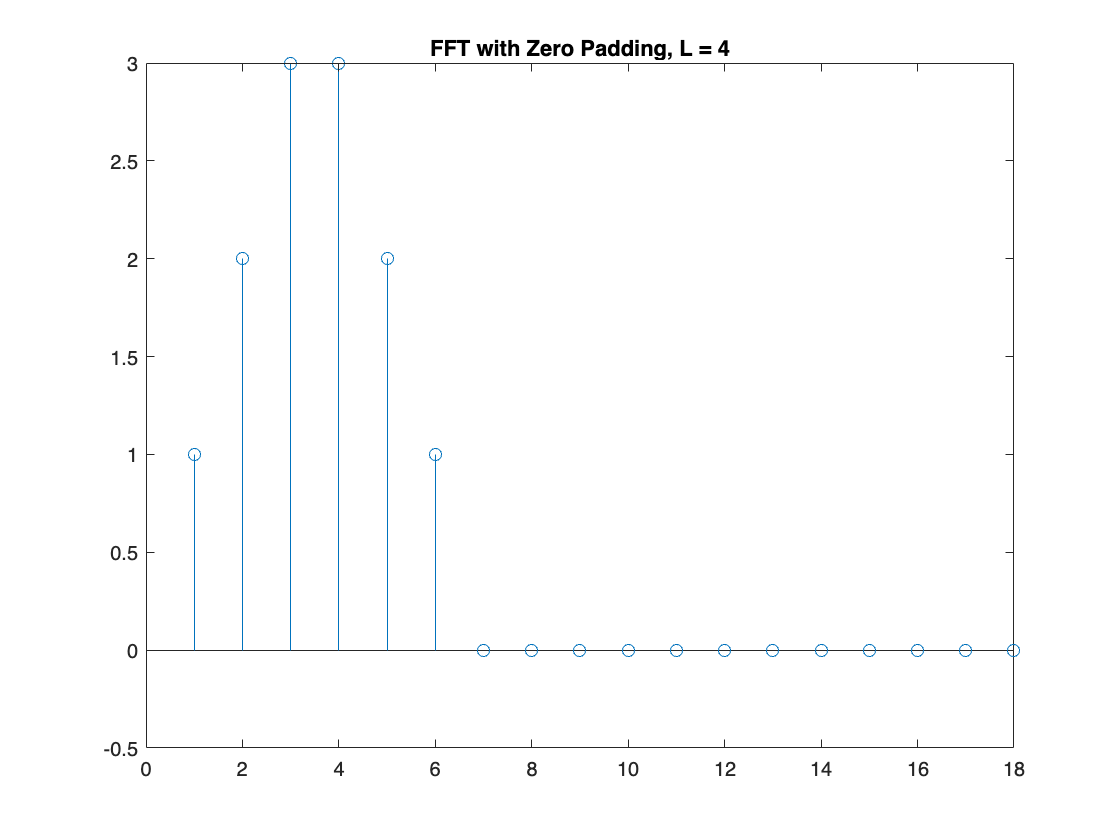

% Part d
% L = 4;
x1p = [1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
x2p = [1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

X1p = fft(x1p, 18);
X2p = fft(x2p, 18);
Y2p = X1p .* X2p;
y2p = ifft(Y2p);
figure;
stem(real(y2p));
title('FFT with Zero Padding, L = 4');

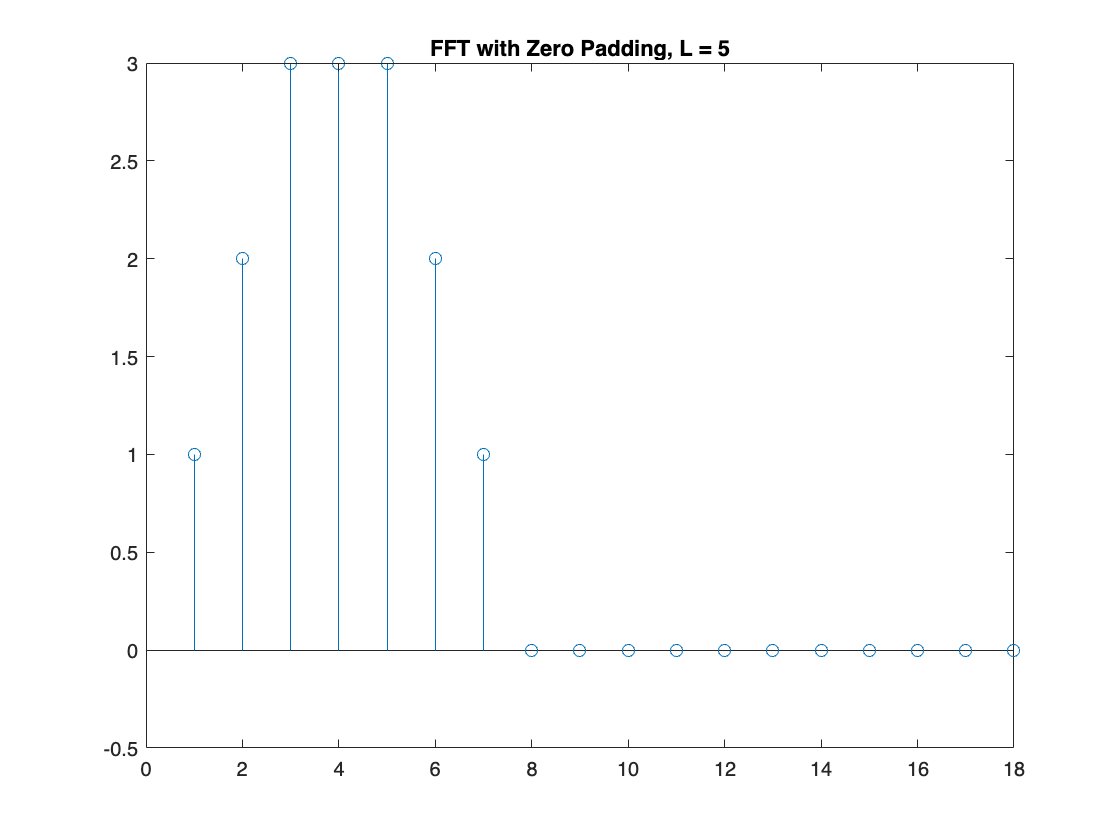

% L = 5;
x1p = [1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0];
x2p = [1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

X1p = fft(x1p, 18);
X2p = fft(x2p, 18);
Y2p = X1p .* X2p;
y2p = ifft(Y2p);
figure;
stem(real(y2p));
title('FFT with Zero Padding, L = 5');

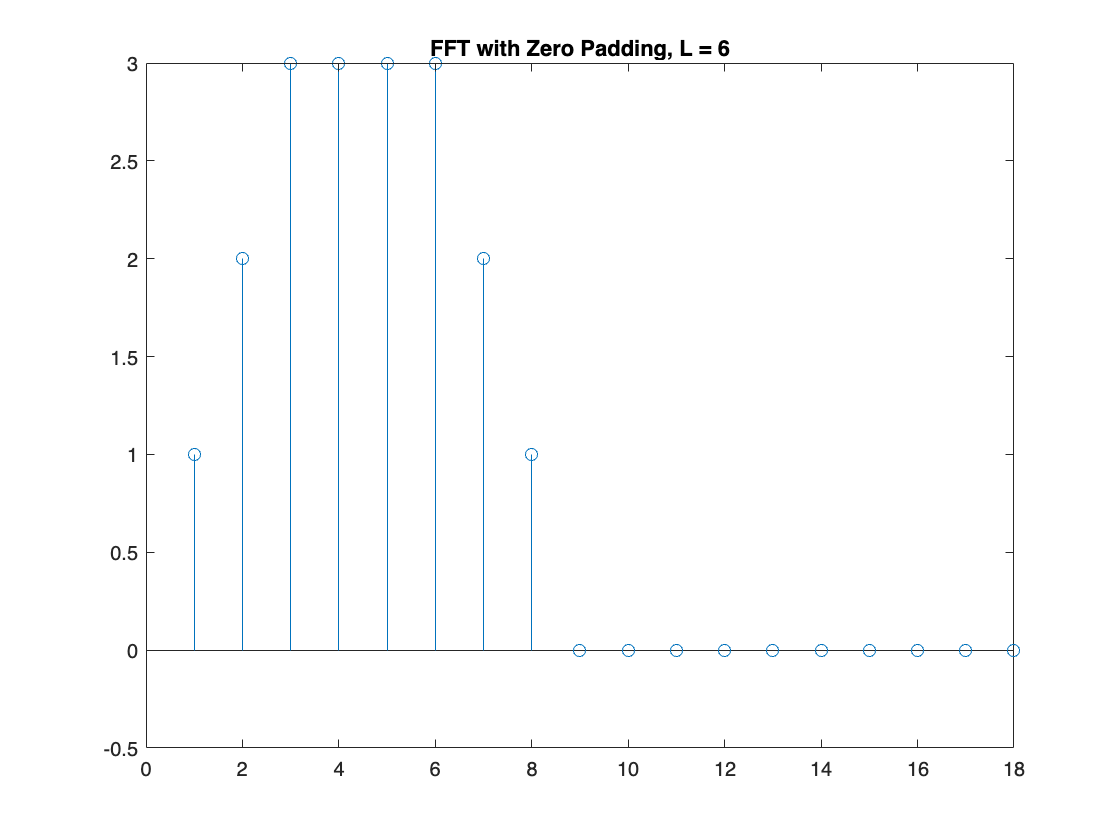

% L = 6;
x1p = [1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0];
x2p = [1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

X1p = fft(x1p, 18);
X2p = fft(x2p, 18);
Y2p = X1p .* X2p;
y2p = ifft(Y2p);
figure;
stem(real(y2p));
title('FFT with Zero Padding, L = 6');

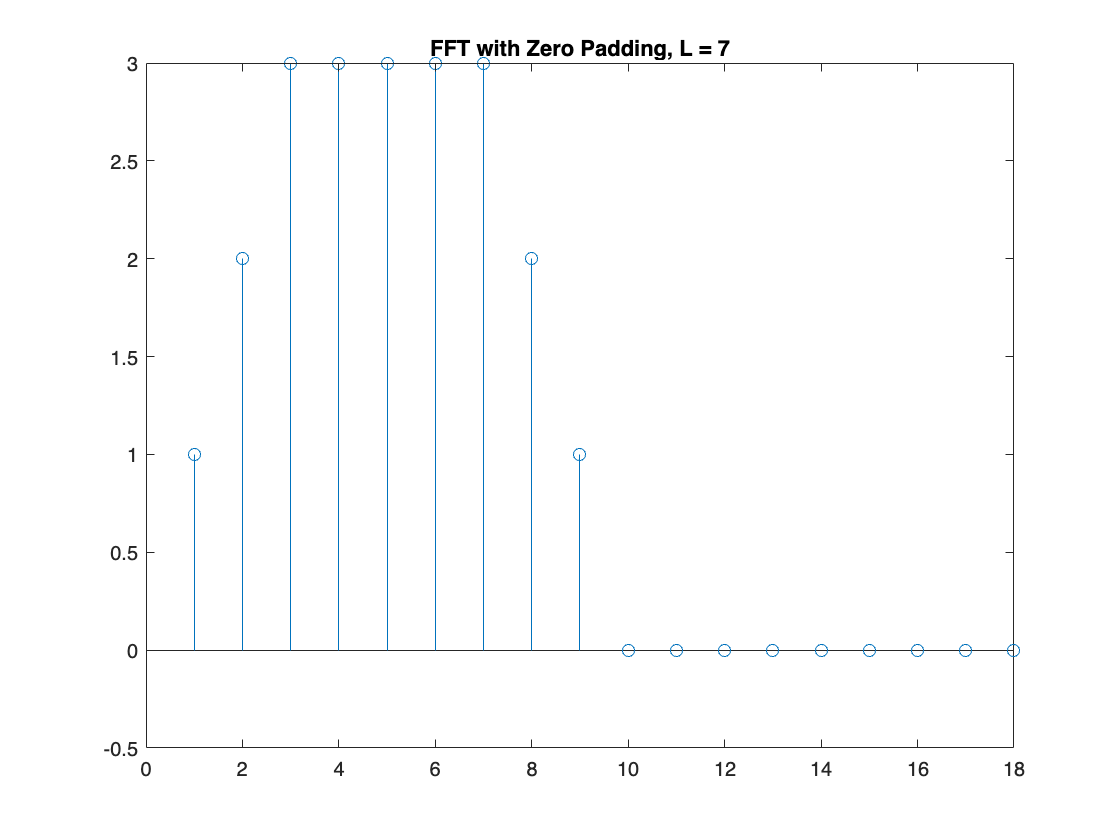

% L = 7;
x1p = [1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0];
x2p = [1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

X1p = fft(x1p, 18);
X2p = fft(x2p, 18);
Y2p = X1p .* X2p;
y2p = ifft(Y2p);
figure;
stem(real(y2p));
title('FFT with Zero Padding, L = 7');

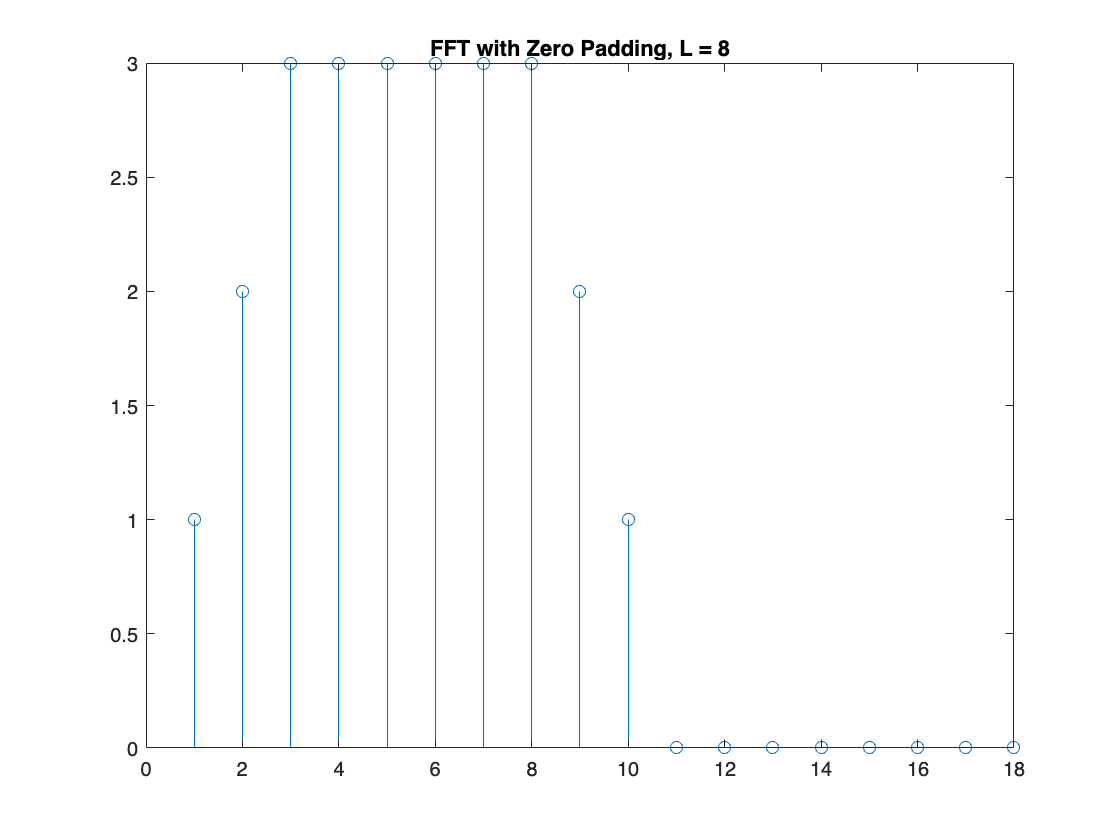

% L = 8;
x1p = [1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0];
x2p = [1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

X1p = fft(x1p, 18);
X2p = fft(x2p, 18);
Y2p = X1p .* X2p;
y2p = ifft(Y2p);
figure;
stem(real(y2p));
title('FFT with Zero Padding, L = 8');

**Explain the impact of increasing the DFT length to 18.**

    There are still the same peaks at the same indexes, however now there are more indexes so L can be increased. 

## Question 5

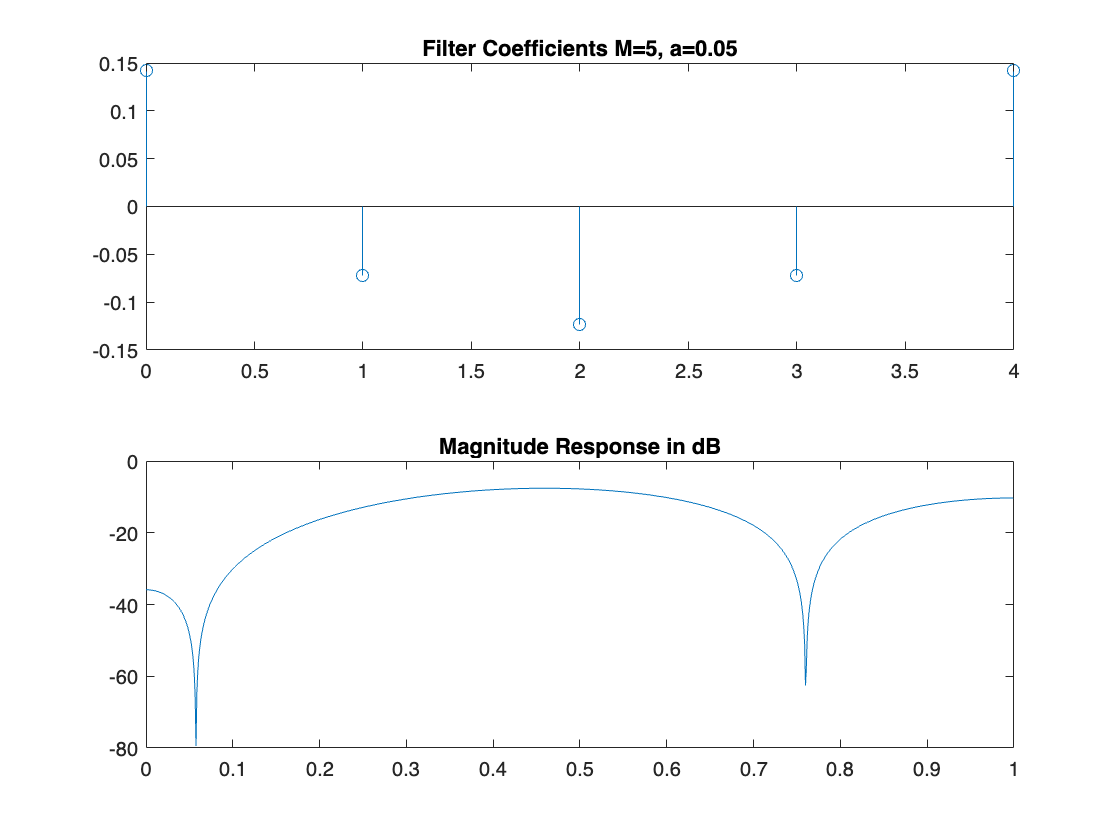

M=5, a=0.05, J=0.1570, Max Response=0.42 at ω/π=0.459


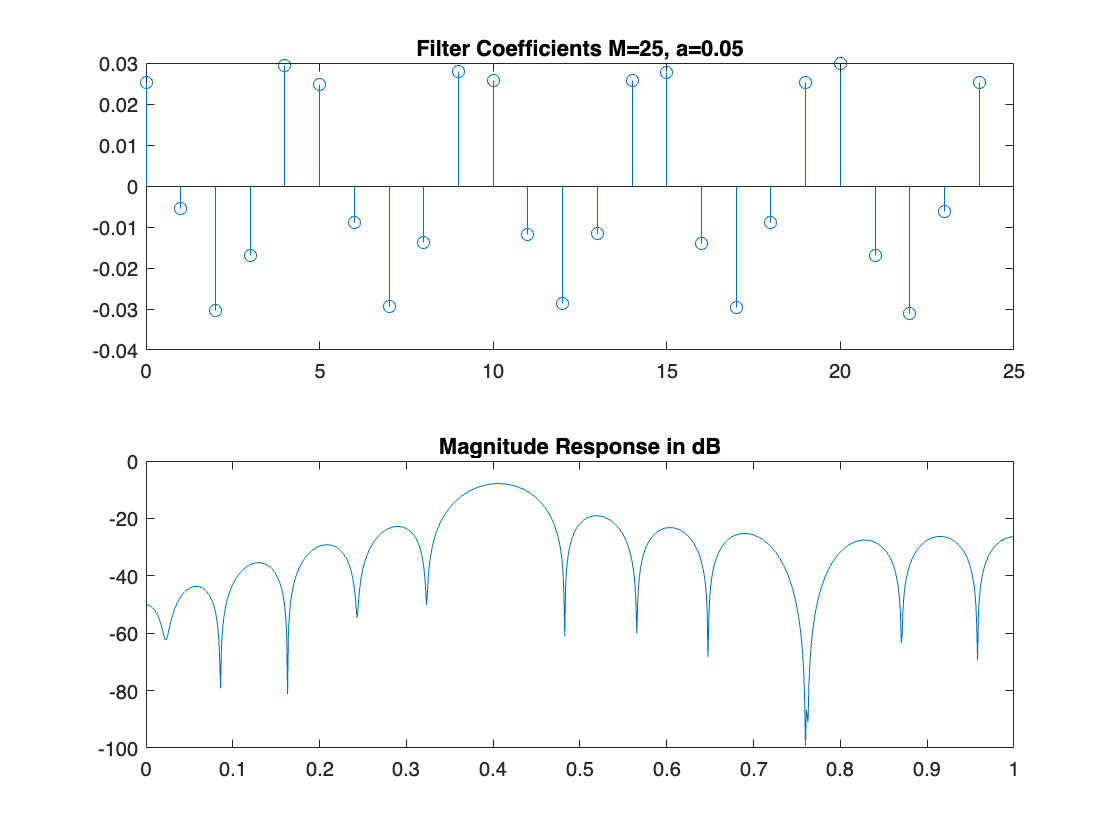

M=25, a=0.05, J=0.0337, Max Response=0.40 at ω/π=0.406


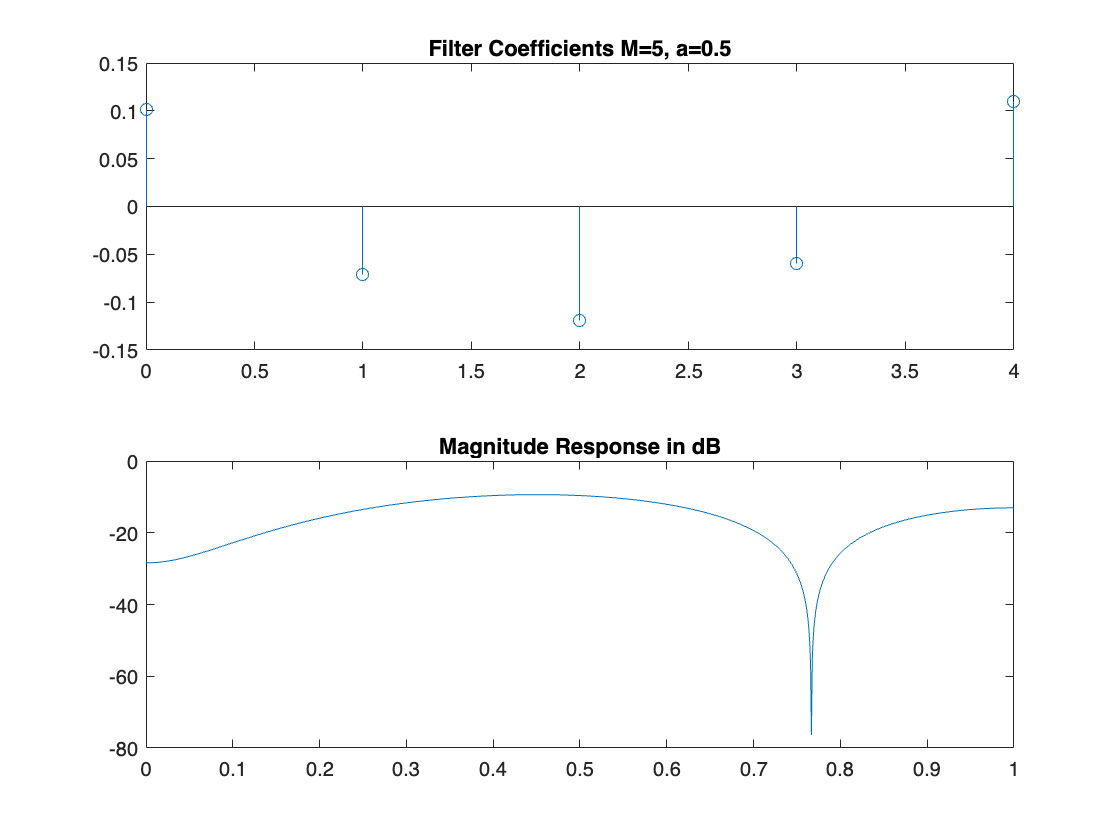

M=5, a=0.50, J=14.4101, Max Response=0.34 at ω/π=0.450


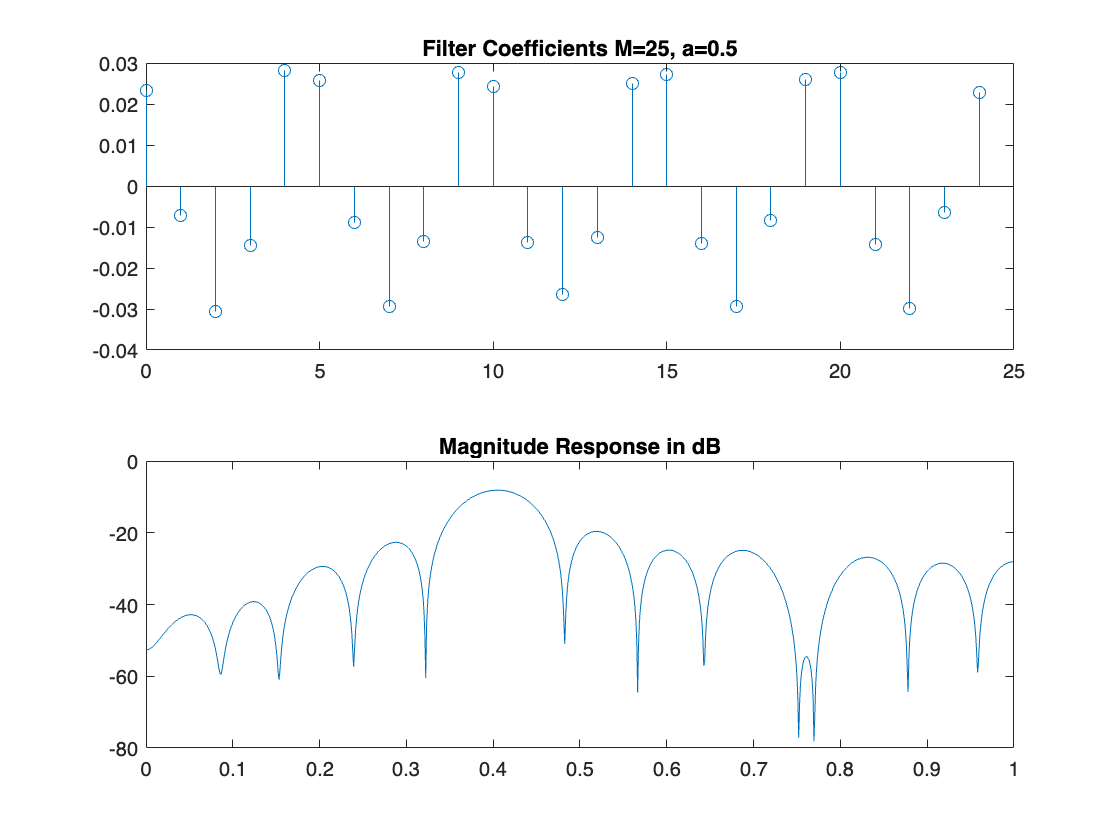

M=25, a=0.50, J=2.8670, Max Response=0.39 at ω/π=0.405


L = 1000;

for a = [0.05, 0.5]
    for M = [5, 25]
        N = M + L - 1;
        n = 0:N-1;

        x = cos(2*pi*0.2*n) + cos(2*pi*0.38*n) + a*randn(1,N);
        d = 0.4*cos(2*pi*0.2*n + pi/5);

        X = zeros(L, M);
        for i = 1:L
            X(i,:) = x(i+M-1:-1:i);
        end
        d_used = d(M:end);

        R = X.' * X;
        P = X.' * d_used.';
        w = R \ P;
        J = sum((X*w - d_used.').^2);

        [H, W] = freqz(w, 1, 1024);
        figure;
        subplot(2,1,1);
        stem(0:M-1, w);
        title(['Filter Coefficients M=' num2str(M) ', a=' num2str(a)]);
        subplot(2,1,2);
        plot(W/pi, 20*log10(abs(H)));
        title('Magnitude Response in dB');

        [max_val, idx] = max(abs(H));
        f_max = W(idx)/pi;
        fprintf('M=%d, a=%.2f, J=%.4f, Max Response=%.2f at ω/π=%.3f\n', M, a, J, max_val, f_max);
    end
end

## Question 6

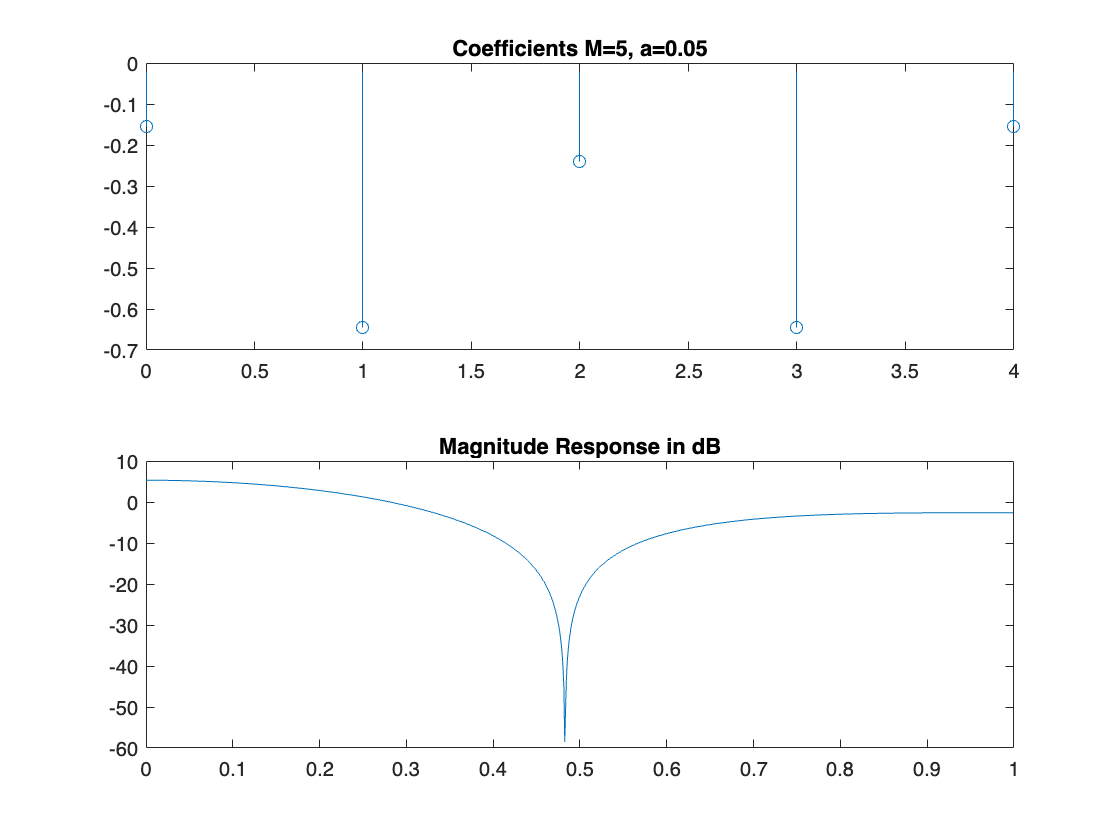

M=5, a=0.05, J=2.5453, Max Response=1.84 at ω/π=0.000


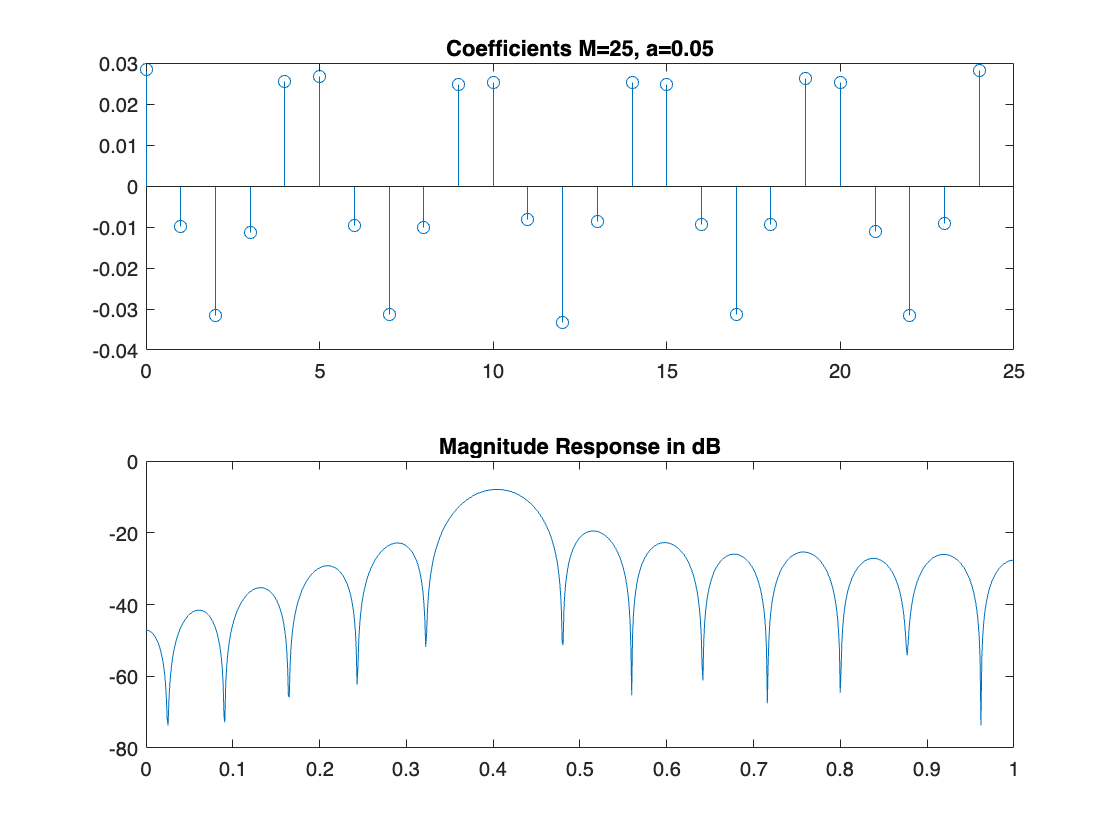

M=25, a=0.05, J=0.0272, Max Response=0.40 at ω/π=0.404


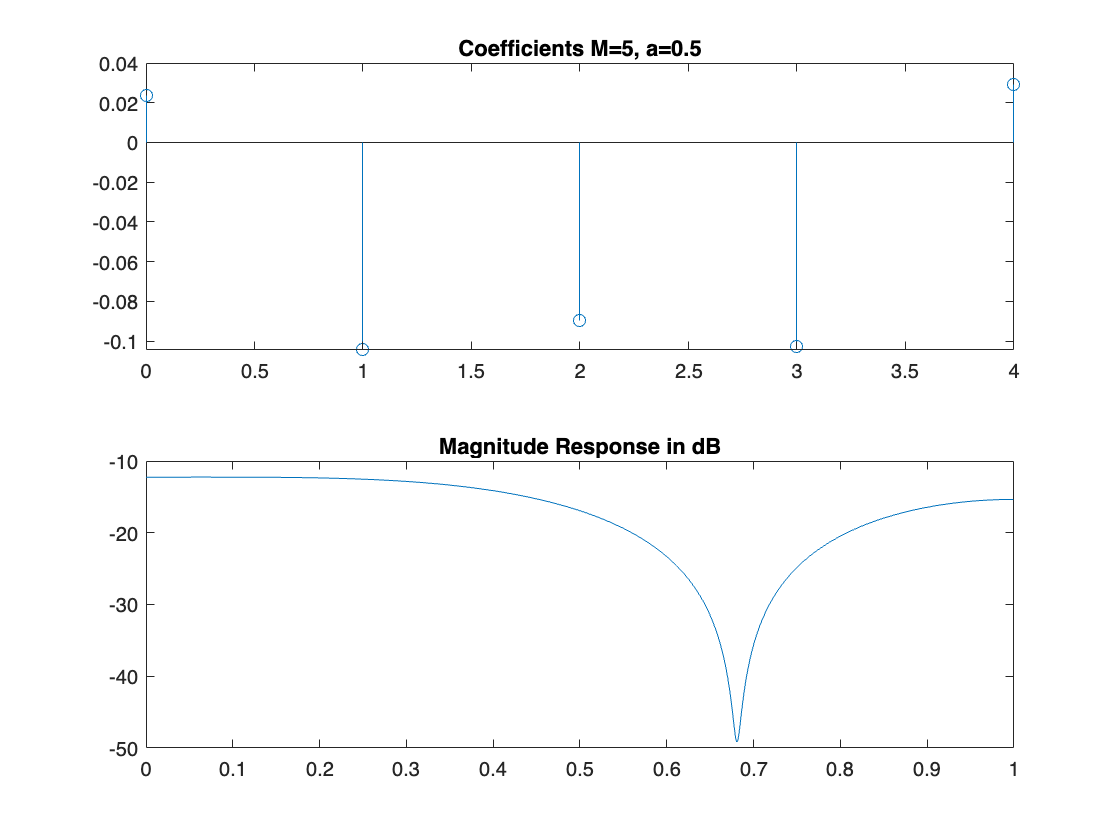

M=5, a=0.50, J=40.4199, Max Response=0.24 at ω/π=0.064


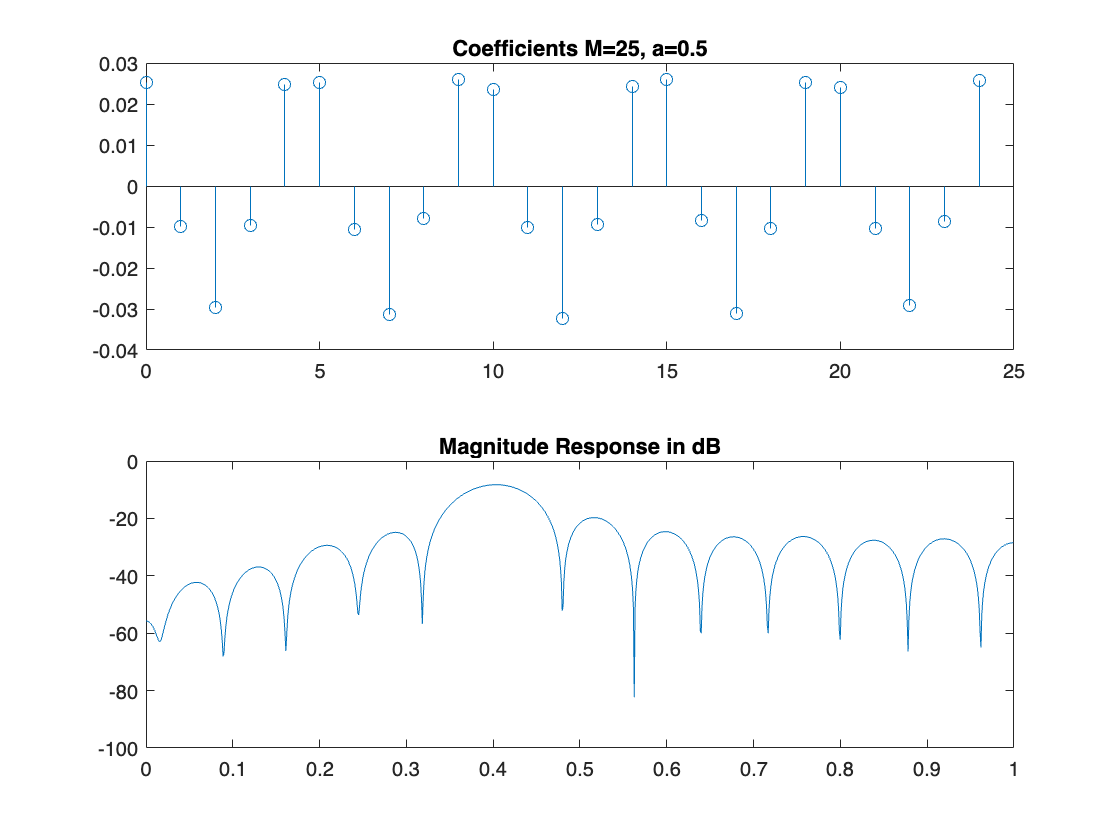

M=25, a=0.50, J=2.7045, Max Response=0.39 at ω/π=0.403


for a = [0.05, 0.5]
    for M = [5, 25]
        N = M + L - 1;
        n = 0:N-1;

        x = cos(2*pi*0.2*n) + cos(2*pi*0.24*n) + a*randn(1,N);
        d = 0.4*cos(2*pi*0.2*n + pi/5);

        X = zeros(L, M);
        for i = 1:L
            X(i,:) = x(i+M-1:-1:i);
        end
        d_used = d(M:end);

        R = X.' * X;
        P = X.' * d_used.';
        w = R \ P;
        J = sum((X*w - d_used.').^2);

        [H, W] = freqz(w, 1, 1024);
        figure;
        subplot(2,1,1);
        stem(0:M-1, w);
        title(['Coefficients M=' num2str(M) ', a=' num2str(a)]);
        subplot(2,1,2);
        plot(W/pi, 20*log10(abs(H)));
        title('Magnitude Response in dB');

        [max_val, idx] = max(abs(H));
        f_max = W(idx)/pi;
        fprintf('M=%d, a=%.2f, J=%.4f, Max Response=%.2f at ω/π=%.3f\n', M, a, J, max_val, f_max);
    end
end

**Explain the differences between these results and the results in Problem 6 in terms of the frequency resolution of the two filter lengths.**

    When there are two frequencies close, only filters with high frequency resolution can separate them.

**What is the impact of the different noise levels in parts (a) and (b) compared to parts (c) and (d)?**

    Noise levels make the filter worse, but longer filters work better.